# **Filter and Manipulate Behaviours**

Preliminary instructions for behaviour extraction. This script will show you how to get behaviour traces, activity bouts and how to manipulate the linits of the activity bouts. Note that the syntax also applies to other function such as the correlation amalys or the dimensionality reduction, where you can perform the analysis using these behavioural filters.

TODO : external_var

# 1. Load existing object

## 1.1 Use the default script to load the object

%% See script to change the default values across the demo scripts
STANDARD_INITIALIZATION()

	INFO : No change detected in time smoothing


lag_list =    -44   -42   -40   -38   -35   -33   -31   -29   -27   -24   -22   -20   -18   -15   -13   -11    -9    -7    -4    -2     0     2     4     7     9    11    13    15    18    20    22    24    27    29    31    33    35    38    40    42    44


lag_smoothing = 0

## 1.2 Display behaviour info

obj.behaviours

ans = struct with fields:
        external_var: {1×30 cell}
       valid_encoder: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
        valid_mc_log: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
               types: {1×14 cell}
    valid_behaviours: [30×14 logical]


Output is a structure with the follwoing fields

        external_var: {1×30 cell}

       valid_encoder: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]

        valid_mc_log: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]

               types: {1×14 cell}

    valid_behaviours: [30×14 logical]

# 2. Display Time Filtered behaviours

We can control the amount of filtering by changing obj.beh_smoothing.

## 2.1. Symetrical filter

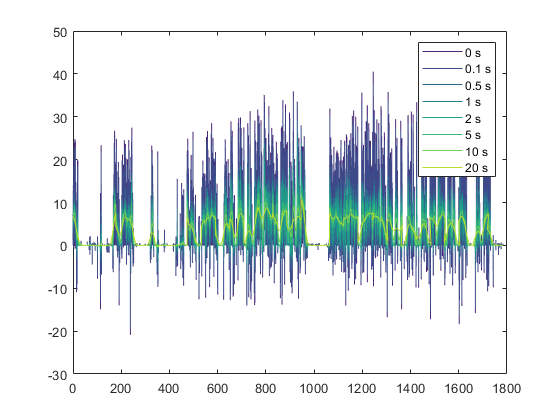

%% Run simulation for every lag value and different smoothing on behaviours
filter_list                         = [0,-0.1,-0.5,-1,-2,-5,-10,-20];
figure();colororder(viridis(numel(filter_list)));
gcf();cla()
for idx = 1:numel(filter_list)
    filter                      = filter_list(idx);
    obj.beh_smoothing           = [filter];
    [~,~,beh]                   = obj.get_behaviours('encoder');
    plot(beh.time, beh.value); hold on;
end
legend(cellfun(@(x) [num2str(abs(x)),' s'], num2cell(filter_list),'UniformOutput',false)); hold on;

set(gcf, 'Color', 'w'); 

## 2.2. Asymetrical filter

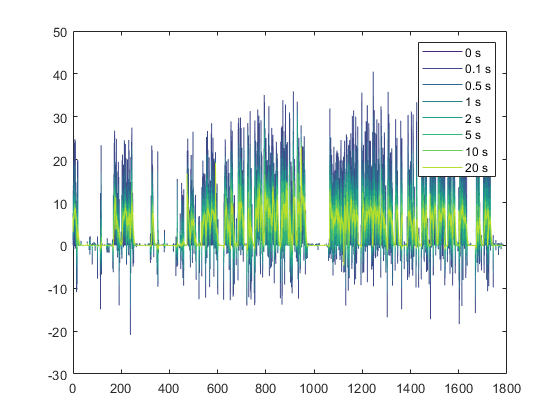

%% Run simulation for every lag value and different smoothing on behaviours
filter_list                         = [0,-0.1,-0.5,-1,-2,-5,-10,-20];
figure();colororder(viridis(numel(filter_list)));
for idx = 1:numel(filter_list)
    filter                      = filter_list(idx);
    obj.beh_smoothing           = [filter, 0];
    [~,~,beh] = obj.get_behaviours('encoder');
    plot(beh.time, beh.value); hold on;
end
legend(cellfun(@(x) [num2str(abs(x)),' s'], num2cell(filter_list),'UniformOutput',false)); hold on;

set(gcf, 'Color', 'w'); 


## 2.3. Detrend vs no - detrend

%% Run simulation for every lag value and different smoothing on behaviours
filter_list                         = [0,-100];
figure();clf();colororder(viridis(numel(filter_list)));
for idx = 1:numel(filter_list)
    filter                      = filter_list(idx);
    obj.beh_smoothing           = -1
    obj.detrend_behaviour       = false;
    [~,~,beh] = obj.get_behaviours('BodyCam_L_whisker');
    plot(beh.time(1,:), beh.value); hold on;
end

obj = 	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	MAJOR WARNING : TRACES HAVE NOT BEEN RESCALED YET - CALL obj.rescale_traces() first 

	WARNING : Global_median_rescaled not available until you called obj.rescale_traces
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation done using all t

obj = 	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	MAJOR WARNING : TRACES HAVE NOT BEEN RESCALED YET - CALL obj.rescale_traces() first 

	WARNING : Global_median_rescaled not available until you called obj.rescale_traces
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation done using all t

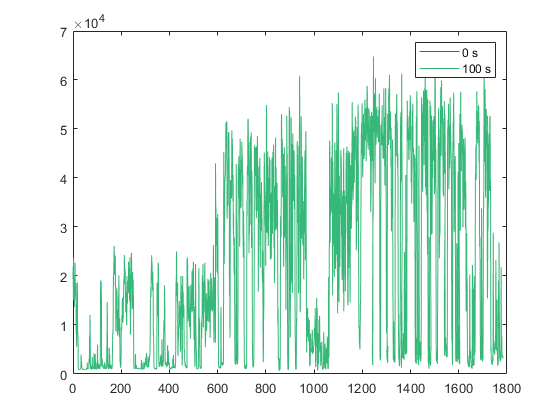

legend(cellfun(@(x) [num2str(abs(x)),' s'], num2cell(filter_list),'UniformOutput',false)); hold on;

set(gcf, 'Color', 'w'); 



# 3. Plot behaviour correlation

## 3.1 Plot a simple correlation matrix between behaviours

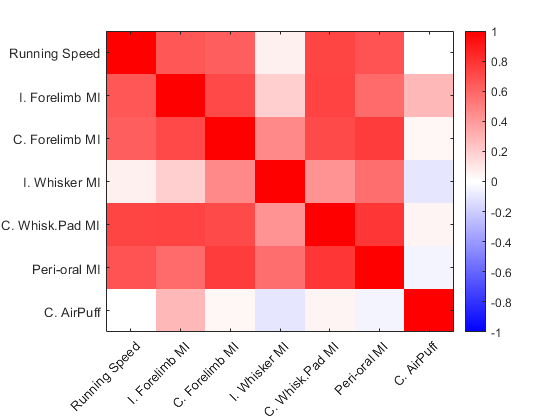

[~, ~, concat_downsamp_beh] = obj.get_behaviours(behaviours);
concat_downsamp_beh = fillmissing(concat_downsamp_beh.value, 'nearest');
concat_downsamp_beh(end, :) = movmean(concat_downsamp_beh(end, :), [27, 0]);
cross_corr = corr(concat_downsamp_beh');
figure();imagesc(cross_corr); hold on;colormap(redblue); hold on;
caxis([-1,1]); hold on;xticks(1:size(cross_corr, 1));yticks(1:size(cross_corr, 1))
colorbar; hold on;set(gcf, 'Color', 'w');
xticklabels(fix_labels(behaviours));xtickangle(45);
yticklabels(fix_labels(behaviours));

## 3.2 Plot behaviour correlation, but just during events

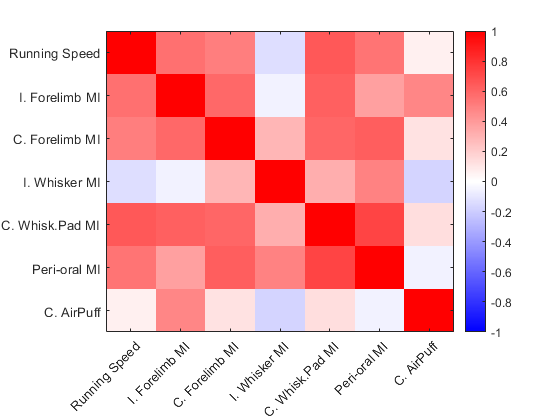

if isempty(obj.event)
    obj.find_events()
end

t = vertcat(obj.event.peak_time{:}); % if not available, you have to run obj.find_events first  

[~, ~, concat_downsamp_beh] = obj.get_behaviours(behaviours);
concat_downsamp_beh.time = concat_downsamp_beh.time(:, t);
concat_downsamp_beh.value = concat_downsamp_beh.value(:, t);
concat_downsamp_beh = fillmissing(concat_downsamp_beh.value, 'nearest');
concat_downsamp_beh(end, :) = movmean(concat_downsamp_beh(end, :), [27, 0]);
cross_corr = corr(concat_downsamp_beh');
figure();imagesc(cross_corr); hold on;colormap(redblue); hold on;
caxis([-1,1]); hold on;xticks(1:size(cross_corr, 1));yticks(1:size(cross_corr, 1))
colorbar; hold on;set(gcf, 'Color', 'w');
xticklabels(fix_labels(behaviours));xtickangle(45);
yticklabels(fix_labels(behaviours));

# 4. Filter and manipulate behaviours

## 4.1 Load and display the encoder behaviour

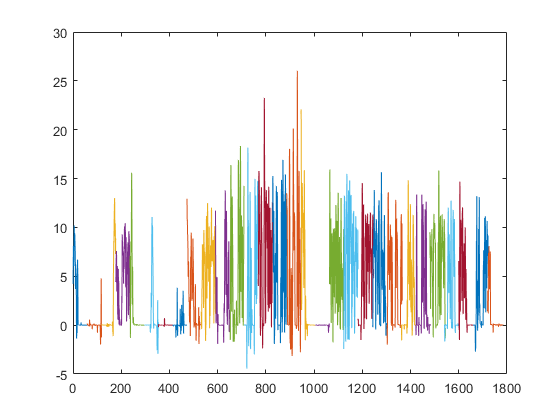

ans = 1×1 cell array
    {1×30 cell}


obj.get_behaviours('encoder', true)

## 4.2 Load and display all behaviours

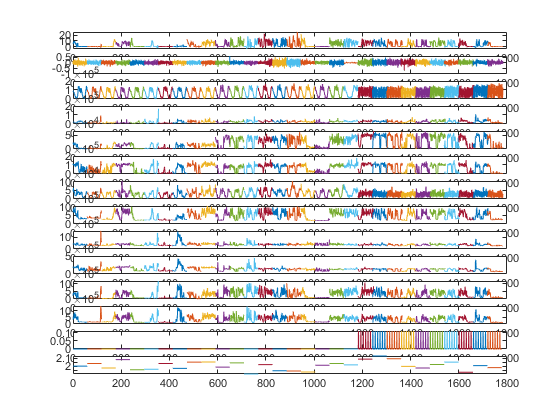

ans = 1×14 cell array
    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}    {1×30 cell}


obj.get_behaviours(obj.behaviours.types, true)

## 4.3 Load all behaviours and capture the concatenated output

[~, ~, concat_downsamp_beh] = obj.get_behaviours(obj.behaviours.types, false);

# 5. Identify behaviour bouts

## 5.1 Detect running bouts

	INFO : N bouts after extension / shrinkage and merging = 32


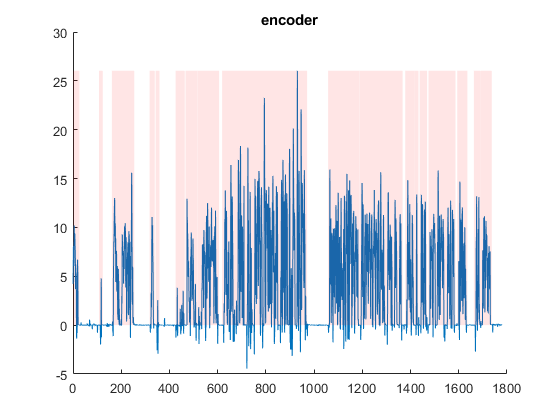

ans = 1×1 cell array
    {[1 235 953 1092 1424 2245 2807 2993 3025 3168 3761 4092 4123 4542 4550 5354 5464 8578 9343 10492 10503 12058 12153 12500 12502 12635 12675 12949 12997 13977 14041 14411 14645 14898 14906 15293]}


obj.get_activity_bout('encoder', true)

## 5.2 Detect running bouts on a more smoothed behaviour

	INFO : N bouts after extension / shrinkage and merging = 24


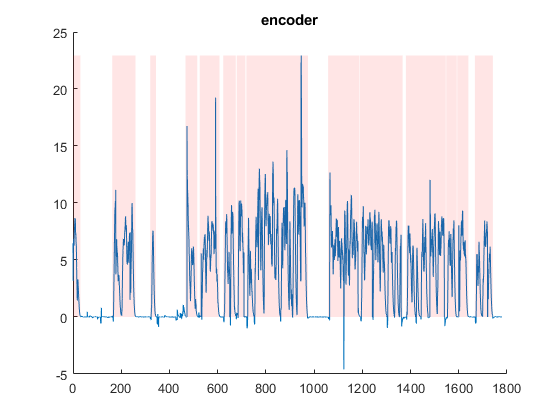

ans = 1×1 cell array
    {[1 270 1436 2291 2830 3039 4123 4549 4645 5365 5503 5961 5997 6316 6349 8610 9347 10494 10514 12058 12177 13624 13641 14024 14041 14445 14680 15337]}


obj.beh_smoothing = [-20,0]; %20s asymetrical gaussian smoothing
obj.get_activity_bout('encoder', true)

## 5.3 Detect running bouts and change the detection threshold

obj.beh_thr = 1; %
obj.get_activity_bout('encoder', true)

	INFO : N bouts after extension / shrinkage and merging = 22


ans = 1×1 cell array
    {[1 306 470 578 844 950 952 1096 1419 2325 2805 3188 3718 5405 5465 8636 9344 12113 12149 14476 14648 15369]}


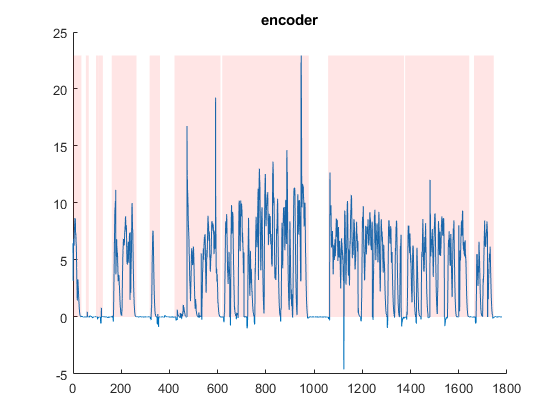

	INFO : N bouts after extension / shrinkage and merging = 24


ans = 1×1 cell array
    {[1 270 1436 2291 2830 3039 4123 4549 4645 5365 5503 5961 5997 6316 6349 8610 9347 10494 10514 12058 12177 13624 13641 14024 14041 14445 14680 15337]}



obj.beh_thr = 10; %
obj.get_activity_bout('encoder', true)

	INFO : N bouts after extension / shrinkage and merging = 39


ans = 1×1 cell array
    {[1 176 1461 1666 1779 2251 2857 2999 4123 4471 4719 5291 5524 5702 5733 5925 6010 6282 6361 6497 6634 7569 7591 8013 8016 8569 9349 10492 10536 11431 11486 11697 11742 11911 11921 12058 12197 12499 12523 12635 12720 12960 12997 13618 13662 13988 14042 14387 14774 14890 14959 15291]}



obj.beh_thr = 50; %
obj.get_activity_bout('encoder', true)

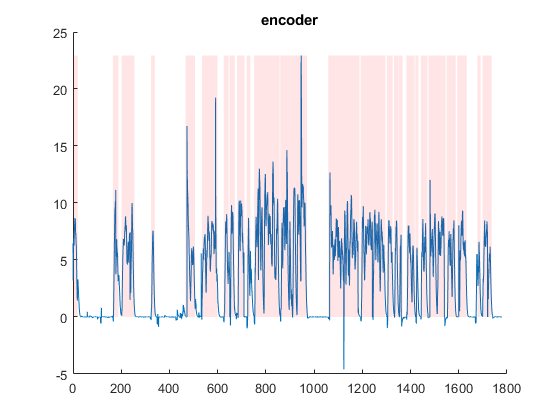

	INFO : N bouts after extension / shrinkage and merging = 14


ans = 1×1 cell array
    {[1513 1619 4123 4259 5167 5279 6719 6903 6972 7187 7256 7412 7777 7908 8034 8290 8299 8500 9355 9470 10137 10255 12997 13107]}



obj.beh_thr = 90; %
obj.get_activity_bout('encoder', true)

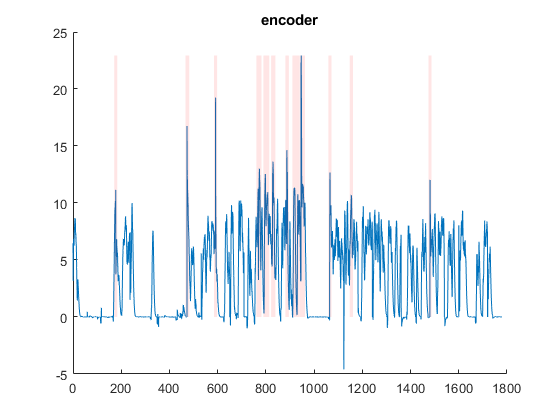

	INFO : N bouts after extension / shrinkage and merging = 9


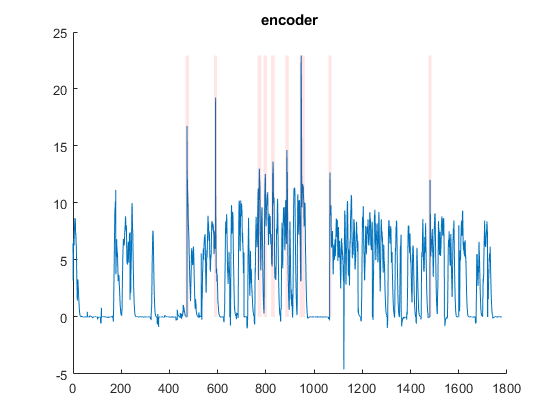

ans = 1×1 cell array
    {[4123 4244 5167 5276 6761 6898 6979 7103 7256 7391 7777 7905 8299 8487 9357 9468 12999 13107]}



obj.beh_thr = 99; %
obj.get_activity_bout('encoder', true)


obj.beh_thr = 10; % restor default

## 5.4 Detect quiet wakefulness bouts 

	INFO : N bouts after extension / shrinkage and merging = 24


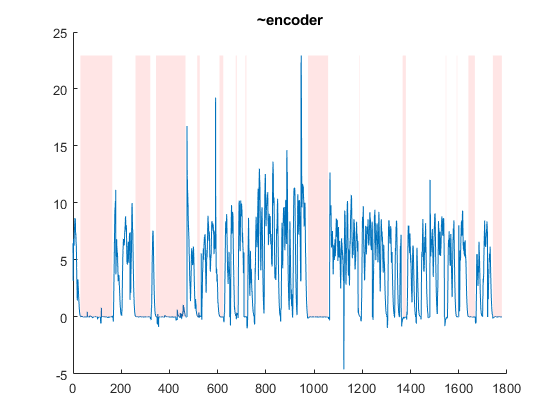

ans = 1×1 cell array
    {[270 1436 2291 2830 3039 4123 4549 4645 5365 5503 5961 5997 6316 6349 8610 9347 10494 10514 12058 12177 13624 13641 14024 14041 14445 14680 15337 15660]}


obj.get_activity_bout('~encoder', true)

## 5.5 Detect activity bouts, and add 3s before and after each bouts

	INFO : N bouts after extension / shrinkage and merging = 24


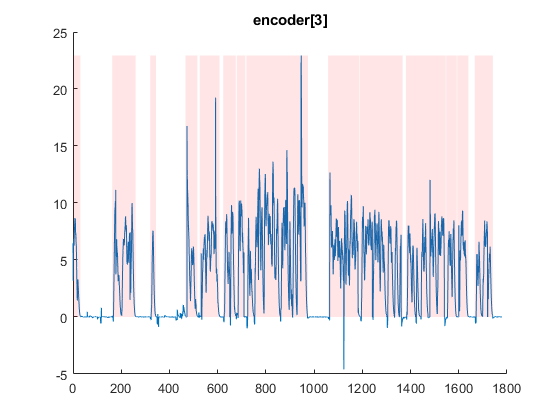

obj.get_activity_bout('encoder[3]', true);

## 5.6 Detect activity bouts, and add 3s before onset 6s after offset of each bouts

	INFO : N bouts after extension / shrinkage and merging = 18


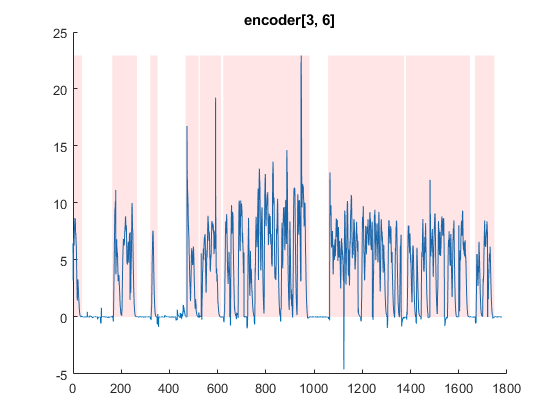

ans = 1×1 cell array
    {[1 324 1436 2345 2830 3093 4123 4603 4645 5419 5503 8664 9347 12112 12177 14499 14680 15391]}


obj.get_activity_bout('encoder[3, 6]', true)

## 5.7 Detect activity bouts, and crop the 2s after onset and 2s before offset

	INFO : N bouts after extension / shrinkage and merging = 33


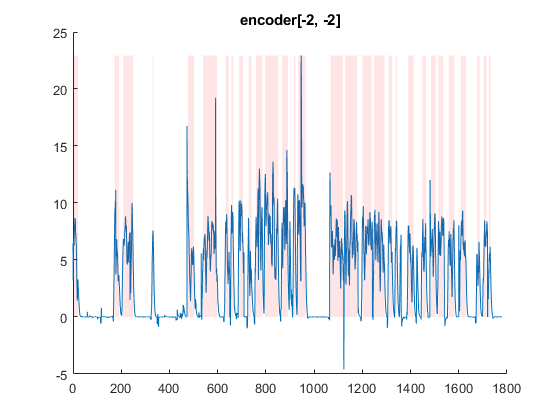

ans = 1×1 cell array
    {[36 182 1524 1689 1836 2203 2918 2951 4211 4430 4761 5273 5591 5706 5809 5873 6085 6228 6437 6540 6699 6940 7035 7516 7662 7870 7957 7967 8089 8147 8247 8522 9435 9891 9965 10406 10602 10926 11023 11400 11556 11682 11811 11861 12265 12455 12771 12913 13085 13256 13359 13536 13729 13936 14165 14357 14768 14853 15002 15102 15184 15249]}


obj.get_activity_bout('encoder[-2, -2]', true)

## 5.8 Detect activity bouts, and set a 5s window preceding the onset by 10s

	INFO : N bouts after extension / shrinkage and merging = 16
	INFO : all detected bouts adjusted to a duration of = 1 seconds before/after onset


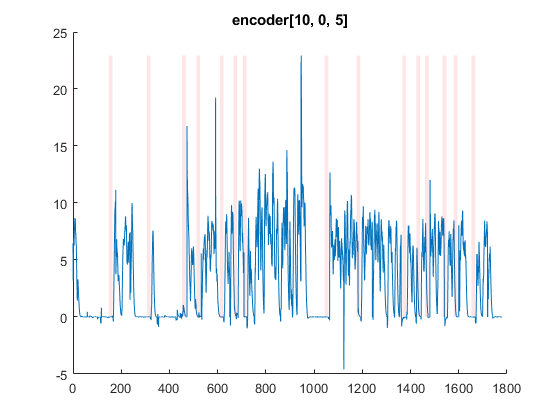

ans = 1×1 cell array
    {[1 45 1312 1445 2706 2839 3999 4132 4521 4654 5379 5512 5873 6006 6225 6358 9223 9356 10390 10523 12053 12186 12559 12692 12873 13006 13517 13650 13917 14050 14556 14689]}


obj.get_activity_bout('encoder[10, 0, 5]', true)

## 5.9 Detect activity bouts, and set a 5s window following the onset by 3s

	INFO : N bouts after extension / shrinkage and merging = 34
	INFO : all detected bouts adjusted to a duration of = 1 seconds before/after onset


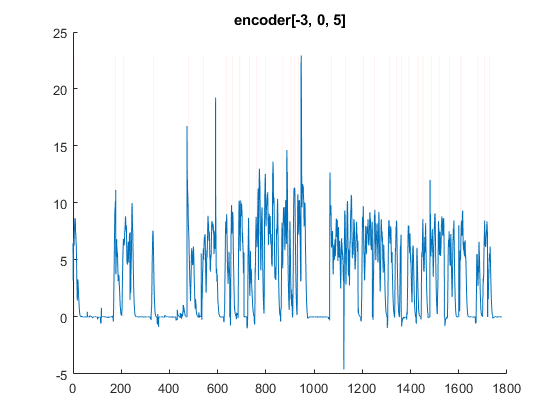

ans = 1×1 cell array
    {[52 71 1540 1559 1852 1871 2934 2953 4227 4246 4777 4796 5607 5626 5825 5844 6101 6120 6453 6472 6715 6734 7051 7070 7678 7697 7973 7992 8105 8124 8263 8282 9451 9470 9981 10000 10618 10637 11039 11058 11572 11591 11827 11846 12003 12022 12281 12300 12613 12632 12787 12806 13101 13120 13375 13394 13745 13764 14145 14164 14181 14200 14784 14803 15018 15037 15200 15219]}


obj.get_activity_bout('encoder[-3, 0, 5]', true)

## 5.10 Detect activity bouts, and set a 5s window preceding the offset by 10s

	INFO : N bouts after extension / shrinkage and merging = 16
	INFO : all detected bouts adjusted to a duration of = 1 seconds before/after offset


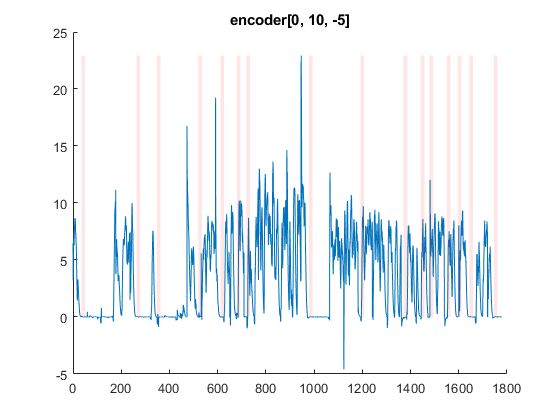

ans = 1×1 cell array
    {[306 439 2327 2460 3074 3207 4589 4722 5401 5534 5996 6129 6351 6484 8645 8778 10529 10662 12093 12226 12719 12852 13036 13169 13659 13792 14059 14192 14481 14614 15372 15505]}


obj.get_activity_bout('encoder[0, 10, -5]', true)

## 5.11 Detect activity bouts, and set a 5s window following the offset by 3s

	INFO : N bouts after extension / shrinkage and merging = 34
	INFO : all detected bouts adjusted to a duration of = 1 seconds before/after offset


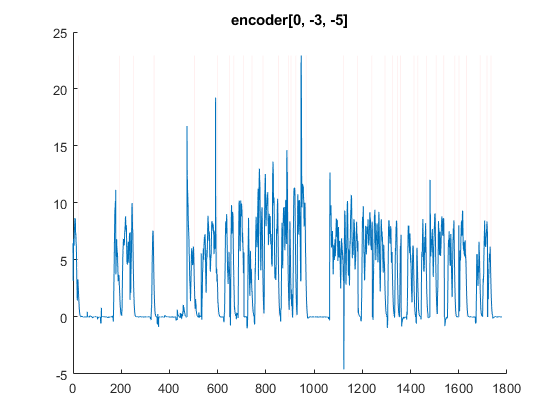

ans = 1×1 cell array
    {[191 210 1698 1717 2212 2231 2960 2979 4439 4458 5282 5301 5715 5734 5882 5901 6237 6256 6549 6568 6950 6969 7525 7544 7879 7898 7976 7995 8156 8175 8531 8550 9900 9919 10415 10434 10935 10954 11410 11429 11691 11710 11870 11889 11979 11998 12464 12483 12605 12624 12922 12941 13265 13284 13545 13564 13945 13964 14095 14114 14366 14385 14862 14881 15111 15130 15258 15277]}


obj.get_activity_bout('encoder[0, -3, -5]', true)